# Benchmark solvers for solving whole body metabolic models

**Authors: Ronan M.T. Fleming, University of Galway**

**Reviewers: **

## Introduction

Compare the time taken to solve different formulations of constraint-based modelling problems involving whole body metabolic models with different solvers and different methods for each solver with the option to repeat the analysis to compute mean and variance of solution times.

## EQUIPMENT SETUP

## **Initialize the COBRA Toolbox.**

Please ensure that The COBRA Toolbox has been properly installed, and initialized using the `initCobraToolbox` function.

if 0 %set to true if your toolbox has not been initialised
    initCobraToolbox(false) % false, as we don't want to update
end

## PROCEDURE 

Define the location to save your results

if 1
    resultsFolder = '~/drive/sbgCloud/projects/variationalKinetics/results/WBM/';
else
    resultsFolder = pwd;
end

Load whole body metabolic model - change this to suit your own setup.

modelToUse ='Harvey';
%modelToUse ='Harvetta';
driver_loadBenchmarkWBMsolvers

## Set  parameters for benchmark

Model perturbation parameters

%model.ub(model.c~=0)=inf;
clear param T T0
param.replaceLargeBoundsWithInf=1;
param.relaxTightBounds=1;
param.relaxTightBounds_lowerExponent = 3; %the minimum difference between ub_j and lb_j is 10^(param.relaxTightBounds_lowerExponent)
param.relaxTightBounds_higherExponent = 10;
param.setUpperBoundOnObjectiveToInf=1;

COBRA toolbox & solver parameters

param.printLevel = 0; %  {(0),1,2} 1 output from optimiseVKmode, 2 also output from solver
param.feasTol = 1e-5;
param.optTol = 1e-5;
param.lifted = 1;
param.multiscale = 1;
param.debug = 0;

Set the maximum time limit allowed to solve a single instance. Useful for eliminating slow instances in a large batch of trials.

param.timelimit = 200;

Select whether to compare one or a set of solvers

compareSolvers = 1;

Select whether to compare one or a set of different formulations of constraint-based modelling problems involving whole body metabolic models.

compareSolveWBMmethods = 1;

Select whether to compare one or a set of available methods (algorithms) for each solver

compareSolverMethods = 1;

Define the number of times to replicate the same formulation, solver, method combination.

nReplicates = 2;

#### Display and (optionally) modify properties of the whole body model that may effect solve time

[nMet,nRxn]=size(model.S)

nMet = 58095

nRxn = 83395

Identify large bounds not at the maximum

boundMagnitudes = [abs(model.lb);abs(model.ub)];
boundMagnitudes(~isfinite(boundMagnitudes))=0;
largestMagnitudeBound = max(boundMagnitudes);
fprintf('%g%s\n',(nnz(largestMagnitudeBound==[abs(model.lb);abs(model.ub)])*100)/(length(model.lb)*2),' = percent of bounds at maximum')

62.2112 = percent of bounds at maximum


Display bounds that are not at the maximum

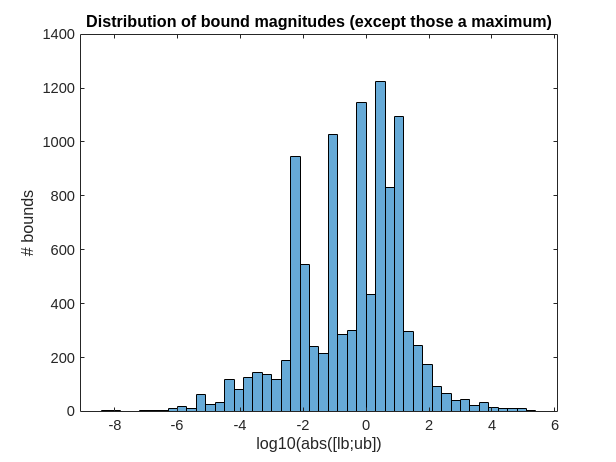

if 1
    figure
    histogram(log10(boundMagnitudes(boundMagnitudes~=largestMagnitudeBound & boundMagnitudes~=0)))
    xlabel('log10(abs([lb;ub])')
    ylabel('# bounds')
    title('Distribution of bound magnitudes (except those a maximum)')
end

Replace large bounds with inf or -inf. This is a good idea. Better to leave this option on.

if param.replaceLargeBoundsWithInf && largestMagnitudeBound>1e3
    model.lb(-largestMagnitudeBound==model.lb)=-inf;
    model.ub(largestMagnitudeBound==model.ub)= inf;
end
boolMagnitudes = boundMagnitudes~=largestMagnitudeBound & boundMagnitudes~=0 & boundMagnitudes<1e-4;
boolRxns = boolMagnitudes(1:nRxn) | boolMagnitudes(nRxn+1:2*nRxn);

Optionally, print the bounds for reactions with small magnitude

if 0
    printFluxBounds(model,model.rxns(boolRxns))
end
fprintf('%g%s\n',nnz(boolRxns)*100/length(boolRxns),' = percent of bounds with magnutide less than 1e-4')

0.389712 = percent of bounds with magnutide less than 1e-4


Optionally, print the bounds for reactions with small difference

boundDifference = model.ub - model.lb;
bool = length(model.rxns);
Z = table(boundDifference,model.rxns,model.rxnNames,'VariableNames',{'boundDifference','rxns','rxnNames'});
if any(boundDifference<0)
    error(['lb > ub for ' num2str(nnz(boundDifference)) ' reactions'])
end
boolDifference = boundDifference<1e-5 & boundDifference~=0;
Z = sortrows(Z(boolDifference,:),'boundDifference');
if 0
    printFluxBounds(model,Z.rxns,1)
end
fprintf('%g%s\n',nnz(boolRxns)*100/length(boolRxns), ' = percent of bounds with difference (ub - lb) less than 1e-5')

0.389712 = percent of bounds with difference (ub - lb) less than 1e-5


forwardBoolDifference = boolDifference & model.lb>=0 & model.ub>0;
reverseBoolDifference = boolDifference & model.lb<0 & model.ub<=0;
reversibleBoolDifference = boolDifference & model.lb<0 & model.ub>0;

if any((forwardBoolDifference | reverseBoolDifference | reversibleBoolDifference)~=boolDifference)
    error('missing bool difference')
end

Optionally relax bounds that are very tight

if param.relaxTightBounds
    modelOld=model;
    done=false(nRxn,1);
    for x=param.relaxTightBounds_higherExponent:-1:param.relaxTightBounds_lowerExponent
        %calulate the difference between the bounds each time
        boundDifference = model.ub - model.lb;

        %forward
        bool = forwardBoolDifference & (boundDifference <= 10^(-x));
        model.ub(bool & ~done) = model.ub(bool & ~done)*(10^(x-param.relaxTightBounds_lowerExponent+1));
        done = done | bool;

        %reverse
        bool = reverseBoolDifference & (boundDifference <= 10^(-x));
        model.lb(bool & ~done) = model.lb(bool & ~done)*(10^(x-param.relaxTightBounds_lowerExponent+1));
        done = done | bool;

        %reversible
        bool = reversibleBoolDifference & (boundDifference <= 10^(-x));
        model.lb(bool & ~done) = model.lb(bool & ~done)*(10^((x-param.relaxTightBounds_lowerExponent+1)/2));
        model.ub(bool & ~done) = model.ub(bool & ~done)*(10^((x-param.relaxTightBounds_lowerExponent+1)/2));
        done = done | bool;

        %reset
        %done=false(nRxn,1);
    end
    fprintf('%g%s\n',nnz(done), [' = reactions with tight bounds relaxed to at least' num2str(param.relaxTightBounds_lowerExponent) ' for ub - lb'])
    if 1
        printFluxBounds(model,Z.rxns,1)
    end
end

69 = reactions with tight bounds relaxed to at least3 for ub - lb


               Reaction ID	   Lower Bound	   Upper Bound
     BBB_ESTRADIOL[CSF]exp	     0.000e+00	     5.544e-03	Estradiol Glucuronide Transport via Bicarbonate Antiport17-Beta-D-Glucuronide Transport (ATP-Dependent)Glucuronidated Compound TransportTransport of EstradiolTransport of Estradiol, Endoplasmatic Reticulum (BBB)
 BBB_LEUKTRB4WCOOH[CSF]exp	     0.000e+00	     7.560e-03	Transport of W-Carboxy Leukotriene B4, Active Transport (BBB)
   BBB_LEUKTRB4WOH[CSF]exp	     0.000e+00	     7.560e-03	Transport of W-Hydroxyl Leukotriene B4, Active TransportTransport of W-Hydroxyl Leukotriene B4, Intracellular Transport (BBB)
             EX_sphings[u]	     0.000e+00	     8.374e-03	Exchange of Sphingosine
            EX_leuktrB4[u]	     0.000e+00	     1.231e-03	Exchange of Leukotriene B4
      BBB_PRGNLONE[CSF]exp	     0.000e+00	     9.576e-03	Steroid SulfotransferaseTransport of Pregnenolone, MitochondrialTransport of Pregnenolone, Endoplasmatic ReticulumTransport of Pregnenolone, Extracell

disp(min(boundDifference(boundDifference~=0)))

   1.0080e-05



Optionally, remove fixed upper bound on biomass reaction

% Optionally, relax bounds that are fixed for the objective
if param.setUpperBoundOnObjectiveToInf
    if any(contains(modelToUse,{'Harvey','Harvetta'})) && nnz(model.c)==1
        biomassRxnAbbr = model.rxns{model.c~=0};
        if model.ub(ismember(model.rxns,biomassRxnAbbr))==model.ub(ismember(model.rxns,biomassRxnAbbr))
            if strcmp(model.osenseStr,'max')
                model.ub(ismember(model.rxns,biomassRxnAbbr))=inf;
            else
                model.lb(ismember(model.rxns,biomassRxnAbbr))=-inf;
            end
        end
    end
end

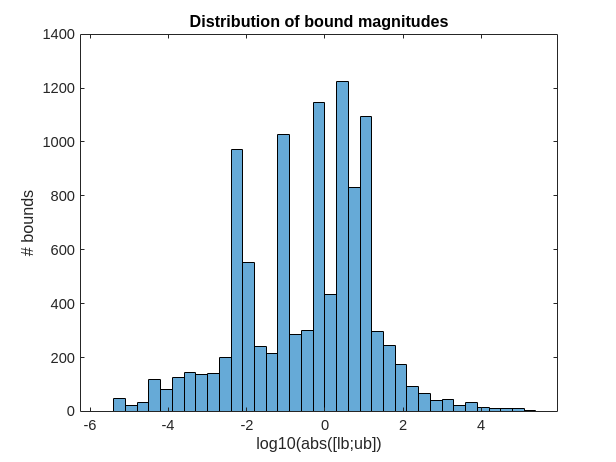

if 1
    boundMagnitudes = [abs(model.lb);abs(model.ub)];
    figure
    histogram(log10(boundMagnitudes))
    xlabel('log10(abs([lb;ub])')
    ylabel('# bounds')
    title('Distribution of bound magnitudes')
end

## Prepare a benchmark table, choose the solver and solve

VariableNames={'interface','solver','method','problem','model','stat','origStat','time','obj','f1','f2','f0'};
% Define the corresponding variable types
VariableTypes = {'string', 'string', 'string','string','string','double','string','double','double','double','double','double'};
T = table('Size', [0 length(VariableNames)],'VariableNames',VariableNames,'VariableTypes', VariableTypes);


Select the solvers to compare

if compareSolvers
    solvers = {'mosek','ibm_cplex','gurobi'};
    %solvers = { 'ibm_cplex','mosek','gurobi'};
    %solvers = { 'mosek','ibm_cplex','gurobi'};
else
    % Choose the solver
    % solvers = {'gurobi'};
    %solvers = {'ibm_cplex'};
    solvers = {'mosek'};
end

Select the formulations to compare

if compareSolveWBMmethods
    %solveWBMmethods = {'LP','QP','QRLP','QRQP','zero','oneInternal'};
    % solveWBMmethods = {'LP','QP'};%,'zero','oneInternal'};
    %solveWBMmethods = {'LP','oneInternal'};
    solveWBMmethods = {'QP','LP'};
else
    % Choose type of problem to solve
    solveWBMmethods = {'LP'};
    %solveWBMmethods = {'QP'};
    %solveWBMmethods = {'QRLP'};
    %solveWBMmethods = {'QRQP'};
end

Define the methods (algorithms) available for different solvers

if compareSolverMethods
    % CPLEX
    % 0	CPX_ALG_AUTOMATIC 	Automatic: let CPLEX choose; default
    % 1	CPX_ALG_PRIMAL 	Primal simplex
    % 2	CPX_ALG_DUAL 	Dual simplex
    % 3	CPX_ALG_NET 	Network simplex
    % 4	CPX_ALG_BARRIER 	Barrier
    % 5	CPX_ALG_SIFTING 	Sifting
    % 6	CPX_ALG_CONCURRENT 	Concurrent (Dual, Barrier, and Primal in opportunistic parallel mode; Dual and Barrier in deterministic parallel mode)
    %https://www.ibm.com/docs/en/icos/12.10.0?topic=parameters-algorithm-continuous-linear-problems
    cplexLPMethods ={'AUTOMATIC','PRIMAL','DUAL','NETWORK','BARRIER','SIFTING','CONCURRENT'};
    % 0	CPX_ALG_AUTOMATIC	Automatic: let CPLEX choose; default
    % 1	CPX_ALG_PRIMAL	Use the primal simplex optimizer.
    % 2	CPX_ALG_DUAL	Use the dual simplex optimizer.
    % 3	CPX_ALG_NET	Use the network optimizer.
    % 4	CPX_ALG_BARRIER	Use the barrier optimizer.
    % 6	CPX_ALG_CONCURRENT	Use the concurrent optimizer.
    % https://www.ibm.com/docs/en/icos/12.10.0?topic=parameters-algorithm-continuous-quadratic-optimization
    cplexQPMethods ={'AUTOMATIC','PRIMAL','DUAL','NETWORK','BARRIER','CONCURRENT'};

    % Mosek

    % MSK_IPAR_OPTIMIZER
    %    The parameter controls which optimizer is used to optimize the task.
    %    Default "FREE"
    %    Accepted "FREE", "INTPNT", "CONIC", "PRIMAL_SIMPLEX", "DUAL_SIMPLEX", "FREE_SIMPLEX", "MIXED_INT"
    %    Example param.MSK_IPAR_OPTIMIZER = 'MSK_OPTIMIZER_FREE'
    mosekLPMethods ={'FREE', 'INTPNT', 'CONIC', 'PRIMAL_SIMPLEX', 'DUAL_SIMPLEX', 'FREE_SIMPLEX'};
    mosekQPMethods ={'FREE', 'INTPNT'}; %CONIC not yet encoded in solveCobraQP

    % Gurobi
    % https://www.gurobi.com/documentation/current/refman/method.html
    % Algorithm used to solve continuous models
    % Algorithm used to solve continuous models or the initial root relaxation of a MIP model. Options are:
    gurobiLPMethods = {'AUTOMATIC','PRIMAL','DUAL','BARRIER','CONCURRENT','DETERMINISTIC_CONCURRENT'};
    gurobiQPMethods = {'AUTOMATIC','PRIMAL','DUAL','BARRIER'};
else
    if 0
        gurobiLPMethods={'BARRIER'};
        gurobiQPMethods={'BARRIER'};
        cplexLPMethods={'BARRIER'};
        cplexQPMethods={'BARRIER'};
        mosekLPMethods = {'CONIC'};
        mosekQPMethods = {'FREE'};
    else
        gurobiLPMethods={'AUTOMATIC'};
        gurobiQPMethods={'AUTOMATIC'};
        cplexLPMethods={'AUTOMATIC'};
        cplexQPMethods={'AUTOMATIC'};
        mosekLPMethods = {'FREE'};
        mosekQPMethods = {'FREE'};
    end
end

Set the min norm weight for QP problems

minNormWeight = 1e-4;
%model.c(:)=0;

Solve the ensemble of instances

for ind = 1:nReplicates
    for i = 1:length(solveWBMmethods)
        param.solveWBMmethod = solveWBMmethods{i};
        switch param.solveWBMmethod
            case 'LP'
                param.minNorm = [];
            case 'QP'
                param.minNorm = minNormWeight;
            case 'QRLP'
                param.minNorm = [];
            case 'QRQP'
                param.minNorm = minNormWeight;
            case 'zero'
                param.minNorm = 'zero';
            case 'oneInternal'
                if isfield(model,'SConsistentRxnBool')
                    param.minNorm = 'oneInternal';
                else
                    error('param.solveWBMmethod = oneInternal cannot be implemented as model.SConsistentRxnBool is missing')
                end
        end

        for j = 1:length(solvers)

            param.solver=solvers{j};

            switch param.solver
                case 'gurobi'
                    if any(strcmp(param.solveWBMmethod,{'LP','zero','oneInternal'}))
                        solverMethods = gurobiLPMethods;
                    else
                        solverMethods = gurobiQPMethods;
                    end
                case 'ibm_cplex'
                    if any(strcmp(param.solveWBMmethod,{'LP','zero','oneInternal'}))
                        solverMethods = cplexLPMethods;
                    else
                        solverMethods = cplexQPMethods;
                    end
                case 'mosek'
                    if any(strcmp(param.solveWBMmethod,{'LP','zero','oneInternal'}))
                        solverMethods = mosekLPMethods;
                    else
                        solverMethods = mosekQPMethods;
                    end
            end

            % Solve a problem with selected solver and each method available to that solver
            for k=1:length(solverMethods)
                if any(strcmp(param.solveWBMmethod,{'LP','zero','oneInternal'}))
                    param.lpmethod = solverMethods{k};
                    if isfield(param,'qpmethod')
                        param = rmfield(param,'qpmethod');
                    end
                else
                    param.qpmethod = solverMethods{k};
                    if isfield(param,'lpmethod')
                        param = rmfield(param,'lpmethod');
                    end
                end
                tic
                try
                    %return
                    solution = optimizeCbModel(model,'min', param.minNorm,1,param);
                catch ME
                    disp('-------------------fail--------------')
                    disp('Error Message:')
                    disp(ME.message)
                    disp(param.solver)
                    disp(solverMethods{k})
                    disp(param.solveWBMmethod)
                    disp(param)
                    disp('-------------------fail--------------')
                end
                T = [T; {'optimizeCbModel', param.solver, solverMethods{k}, param.solveWBMmethod, modelToUse, solution.stat,{solution.origStat},toc,{solution.obj},{solution.f1},{solution.f2},{solution.f0}}];
                %display(T(end,:));
            end
            display(T)
        end
    end
end

  1×12 table

        interface        solver     method    problem     model      stat    origStat     time          obj           f1            f2            f0   
    _________________    _______    ______    _______    ________    ____    _________    _____    ______________    _____    ______________    _______

    "optimizeCbModel"    "mosek"    "FREE"     "QP"      "Harvey"     1      "OPTIMAL"    62.06    {[7.0353e+06]}    {[0]}    {[7.0353e+06]}    {[NaN]}

  1×12 <a href="matlab:helpPopup('table')" style="font-

T = 2×12 table
        interface        solver      method     problem     model      stat    origStat      time          obj           f1            f2            f0   
    _________________    _______    ________    _______    ________    ____    _________    ______    ______________    _____    ______________    _______

    "optimizeCbModel"    "mosek"    "FREE"       "QP"      "Harvey"     1      "OPTIMAL"     62.06    {[7.0353e+06]}    {[0]}    {[7.0353e+06]}    {[NaN]}
    "optimizeCbModel"    "mosek"    "INTPNT"     "QP"      "Harvey"     1      "OPTIMAL"    62.152    {[7.0353e

  1×12 table

        interface          solver         method       problem     model      stat      origStat        time          obj           f1            f2            f0   
    _________________    ___________    ___________    _______    ________    ____    _____________    ______    ______________    _____    ______________    _______

    "optimizeCbModel"    "ibm_cplex"    "AUTOMATIC"     "QP"      "Harvey"     3      "non-optimal"    30.437    {[7.0408e+06]}    {[0]}    {[7.0408e+06]}    {[NaN]}

  1×12 <a hre

T = 8×12 table
        interface          solver          method       problem     model      stat          origStat            time          obj            f1             f2            f0   
    _________________    ___________    ____________    _______    ________    ____    _____________________    ______    ______________    _______    ______________    _______

    "optimizeCbModel"    "mosek"        "FREE"           "QP"      "Harvey"      1     "OPTIMAL"                 62.06    {[7.0353e+06]}    {[  0]}    {[7.0353e+06]}    {[NaN]}
    "optimizeCbModel"    "mosek"        "INTP

  1×12 table

        interface         solver       method       problem     model      stat      origStat       time       obj        f1         f2         f0   
    _________________    ________    ___________    _______    ________    ____    ____________    ______    _______    _______    _______    _______

    "optimizeCbModel"    "gurobi"    "AUTOMATIC"     "QP"      "Harvey"     -1     "TIME_LIMIT"    201.78    {[NaN]}    {[NaN]}    {[NaN]}    {[NaN]}

  1×12 <a href="matlab:helpPopup('table')" style="font-weight

T = 12×12 table
        interface          solver          method       problem     model      stat          origStat            time          obj            f1             f2            f0   
    _________________    ___________    ____________    _______    ________    ____    _____________________    ______    ______________    _______    ______________    _______

    "optimizeCbModel"    "mosek"        "FREE"           "QP"      "Harvey"      1     "OPTIMAL"                 62.06    {[7.0353e+06]}    {[  0]}    {[7.0353e+06]}    {[NaN]}
    "optimizeCbModel"    "mosek"        "INT

  1×12 table

        interface        solver     method    problem     model      stat    origStat      time        obj            f1          f2         f0   
    _________________    _______    ______    _______    ________    ____    _________    ______    __________    __________    _______    _______

    "optimizeCbModel"    "mosek"    "FREE"     "LP"      "Harvey"     1      "OPTIMAL"    23.359    {[2.6571]}    {[2.6571]}    {[NaN]}    {[NaN]}

  1×12 ta

OPTIMAL


  1×12 table

        interface        solver     method     problem     model      stat    origStat      time        obj            f1          f2         f0   
    _________________    _______    _______    _______    ________    ____    _________    ______    __________    __________    _______    _______

    "optimizeCbModel"    "mosek"    "CONIC"     "LP"      "Harvey"     1      "OPTIMAL"    16.838    {[2.7693]}    {[2.7693]}    {[NaN]}    {[NaN]}



Mosek returned an error or warning, open the following link in your browser:
<a href="https://docs.mosek.com/latest/toolbox/response-codes.html#mosek.rescode.trm_max_time">https://docs.mosek.com/latest/toolbox/response-codes.html#mosek.rescode.trm_max_time</a>


  1×12 table

        interface        solver          method         problem     model      stat                   origStat                   time       obj        f1         f2         f0   
    _________________    _______    ________________    _______    ________    ____    ______________________________________    _____    _______    _______    _______    _______

    "optimizeCbModel"    "mosek"    "PRIMAL_SIMPLEX"     "LP"      "Harvey"     -1     "DUAL_FEASIBLE & MSK_RES_TRM_MAX_TIME"    200.9    {[NaN]}    {[NaN

Mosek returned an error or warning, open the following link in your browser:
<a href="https://docs.mosek.com/latest/toolbox/response-codes.html#mosek.rescode.trm_max_time">https://docs.mosek.com/latest/toolbox/response-codes.html#mosek.rescode.trm_max_time</a>


  1×12 table

        interface        solver         method        problem     model      stat                origStat                 time       obj        f1         f2         f0   
    _________________    _______    ______________    _______    ________    ____    ________________________________    ______    _______    _______    _______    _______

    "optimizeCbModel"    "mosek"    "DUAL_SIMPLEX"     "LP"      "Harvey"     -1     "UNKNOWN & MSK_RES_TRM_MAX_TIME"    206.15    {[NaN]}    {[NaN]}    {[NaN]}    {[Na

Mosek returned an error or warning, open the following link in your browser:
<a href="https://docs.mosek.com/latest/toolbox/response-codes.html#mosek.rescode.trm_max_time">https://docs.mosek.com/latest/toolbox/response-codes.html#mosek.rescode.trm_max_time</a>


  1×12 table

        interface        solver         method        problem     model      stat                origStat                 time       obj        f1         f2         f0   
    _________________    _______    ______________    _______    ________    ____    ________________________________    ______    _______    _______    _______    _______

    "optimizeCbModel"    "mosek"    "FREE_SIMPLEX"     "LP"      "Harvey"     -1     "UNKNOWN & MSK_RES_TRM_MAX_TIME"    205.42    {[NaN]}    {[NaN]}    {[NaN]}    {[Na

T = 18×12 table
        interface          solver            method         problem     model      stat                   origStat                    time          obj              f1              f2            f0   
    _________________    ___________    ________________    _______    ________    ____    ______________________________________    ______    ______________    __________    ______________    _______

    "optimizeCbModel"    "mosek"        "FREE"               "QP"      "Harvey"      1     "OPTIMAL"                                  62.06    {[7.0353e+06]}    {[     0]}  

  1×12 table

        interface          solver         method       problem     model      stat    origStat      time        obj            f1          f2         f0   
    _________________    ___________    ___________    _______    ________    ____    _________    ______    __________    __________    _______    _______

    "optimizeCbModel"    "ibm_cplex"    "AUTOMATIC"     "LP"      "Harvey"     1      "optimal"    17.237    {[2.6571]}    {[2.6571]}    {[NaN]}    {[NaN]}

  1×12 

T = 25×12 table
        interface          solver            method         problem     model      stat                   origStat                    time          obj              f1              f2            f0   
    _________________    ___________    ________________    _______    ________    ____    ______________________________________    ______    ______________    __________    ______________    _______

    "optimizeCbModel"    "mosek"        "FREE"               "QP"      "Harvey"      1     "OPTIMAL"                                  62.06    {[7.0353e+06]}    {[     0]}  

  1×12 table

        interface         solver       method       problem     model      stat    origStat      time        obj            f1          f2         f0   
    _________________    ________    ___________    _______    ________    ____    _________    ______    __________    __________    _______    _______

    "optimizeCbModel"    "gurobi"    "AUTOMATIC"     "LP"      "Harvey"     1      "OPTIMAL"    41.334    {[2.6571]}    {[2.6571]}    {[NaN]}    {[NaN]}

  1×12 <a href="matlab:helpPopup('table')" style="fo

T = 31×12 table
        interface          solver            method         problem     model      stat                   origStat                    time          obj              f1              f2            f0   
    _________________    ___________    ________________    _______    ________    ____    ______________________________________    ______    ______________    __________    ______________    _______

    "optimizeCbModel"    "mosek"        "FREE"               "QP"      "Harvey"      1     "OPTIMAL"                                  62.06    {[7.0353e+06]}    {[     0]}  

  1×12 table

        interface        solver     method    problem     model      stat    origStat      time          obj           f1            f2            f0   
    _________________    _______    ______    _______    ________    ____    _________    ______    ______________    _____    ______________    _______

    "optimizeCbModel"    "mosek"    "FREE"     "QP"      "Harvey"     1      "OPTIMAL"    61.866    {[7.0353e+06]}    {[0]}    {[7.0353e+06]}    {[NaN]}

  1×12 <a href="matlab:helpPopup('table')" style="fo

T = 33×12 table
        interface          solver            method         problem     model      stat                   origStat                    time          obj              f1              f2            f0   
    _________________    ___________    ________________    _______    ________    ____    ______________________________________    ______    ______________    __________    ______________    _______

    "optimizeCbModel"    "mosek"        "FREE"               "QP"      "Harvey"      1     "OPTIMAL"                                  62.06    {[7.0353e+06]}    {[     0]}  

  1×12 table

        interface          solver         method       problem     model      stat      origStat        time          obj           f1            f2            f0   
    _________________    ___________    ___________    _______    ________    ____    _____________    ______    ______________    _____    ______________    _______

    "optimizeCbModel"    "ibm_cplex"    "AUTOMATIC"     "QP"      "Harvey"     3      "non-optimal"    30.179    {[7.0408e+06]}    {[0]}    {[7.0408e+06]}    {[NaN]}

  1×12 <a hre

T = 39×12 table
        interface          solver            method         problem     model      stat                   origStat                    time          obj              f1              f2            f0   
    _________________    ___________    ________________    _______    ________    ____    ______________________________________    ______    ______________    __________    ______________    _______

    "optimizeCbModel"    "mosek"        "FREE"               "QP"      "Harvey"      1     "OPTIMAL"                                  62.06    {[7.0353e+06]}    {[     0]}  

  1×12 table

        interface         solver       method       problem     model      stat      origStat       time       obj        f1         f2         f0   
    _________________    ________    ___________    _______    ________    ____    ____________    ______    _______    _______    _______    _______

    "optimizeCbModel"    "gurobi"    "AUTOMATIC"     "QP"      "Harvey"     -1     "TIME_LIMIT"    201.39    {[NaN]}    {[NaN]}    {[NaN]}    {[NaN]}

  1×12 <a href="matlab:helpPopup('table')" style="font-weight

T = 43×12 table
        interface          solver            method         problem     model      stat                   origStat                    time          obj              f1              f2            f0   
    _________________    ___________    ________________    _______    ________    ____    ______________________________________    ______    ______________    __________    ______________    _______

    "optimizeCbModel"    "mosek"        "FREE"               "QP"      "Harvey"      1     "OPTIMAL"                                  62.06    {[7.0353e+06]}    {[     0]}  

  1×12 table

        interface        solver     method    problem     model      stat    origStat      time        obj            f1          f2         f0   
    _________________    _______    ______    _______    ________    ____    _________    ______    __________    __________    _______    _______

    "optimizeCbModel"    "mosek"    "FREE"     "LP"      "Harvey"     1      "OPTIMAL"    23.077    {[2.6571]}    {[2.6571]}    {[NaN]}    {[NaN]}

  1×12 ta

OPTIMAL


  1×12 table

        interface        solver     method     problem     model      stat    origStat      time        obj            f1          f2         f0   
    _________________    _______    _______    _______    ________    ____    _________    ______    __________    __________    _______    _______

    "optimizeCbModel"    "mosek"    "CONIC"     "LP"      "Harvey"     1      "OPTIMAL"    16.841    {[2.7693]}    {[2.7693]}    {[NaN]}    {[NaN]}



Mosek returned an error or warning, open the following link in your browser:
<a href="https://docs.mosek.com/latest/toolbox/response-codes.html#mosek.rescode.trm_max_time">https://docs.mosek.com/latest/toolbox/response-codes.html#mosek.rescode.trm_max_time</a>


  1×12 table

        interface        solver          method         problem     model      stat                   origStat                    time       obj        f1         f2         f0   
    _________________    _______    ________________    _______    ________    ____    ______________________________________    ______    _______    _______    _______    _______

    "optimizeCbModel"    "mosek"    "PRIMAL_SIMPLEX"     "LP"      "Harvey"     -1     "DUAL_FEASIBLE & MSK_RES_TRM_MAX_TIME"    202.11    {[NaN]}    {[

Mosek returned an error or warning, open the following link in your browser:
<a href="https://docs.mosek.com/latest/toolbox/response-codes.html#mosek.rescode.trm_max_time">https://docs.mosek.com/latest/toolbox/response-codes.html#mosek.rescode.trm_max_time</a>


  1×12 table

        interface        solver         method        problem     model      stat                origStat                 time       obj        f1         f2         f0   
    _________________    _______    ______________    _______    ________    ____    ________________________________    ______    _______    _______    _______    _______

    "optimizeCbModel"    "mosek"    "DUAL_SIMPLEX"     "LP"      "Harvey"     -1     "UNKNOWN & MSK_RES_TRM_MAX_TIME"    202.08    {[NaN]}    {[NaN]}    {[NaN]}    {[Na

Mosek returned an error or warning, open the following link in your browser:
<a href="https://docs.mosek.com/latest/toolbox/response-codes.html#mosek.rescode.trm_max_time">https://docs.mosek.com/latest/toolbox/response-codes.html#mosek.rescode.trm_max_time</a>


  1×12 table

        interface        solver         method        problem     model      stat                origStat                 time       obj        f1         f2         f0   
    _________________    _______    ______________    _______    ________    ____    ________________________________    ______    _______    _______    _______    _______

    "optimizeCbModel"    "mosek"    "FREE_SIMPLEX"     "LP"      "Harvey"     -1     "UNKNOWN & MSK_RES_TRM_MAX_TIME"    205.95    {[NaN]}    {[NaN]}    {[NaN]}    {[Na

T = 49×12 table
        interface          solver            method         problem     model      stat                   origStat                    time          obj              f1              f2            f0   
    _________________    ___________    ________________    _______    ________    ____    ______________________________________    ______    ______________    __________    ______________    _______

    "optimizeCbModel"    "mosek"        "FREE"               "QP"      "Harvey"      1     "OPTIMAL"                                  62.06    {[7.0353e+06]}    {[     0]}  

  1×12 table

        interface          solver         method       problem     model      stat    origStat      time        obj            f1          f2         f0   
    _________________    ___________    ___________    _______    ________    ____    _________    ______    __________    __________    _______    _______

    "optimizeCbModel"    "ibm_cplex"    "AUTOMATIC"     "LP"      "Harvey"     1      "optimal"    17.153    {[2.6571]}    {[2.6571]}    {[NaN]}    {[NaN]}

  1×12 

T = 56×12 table
        interface          solver            method         problem     model      stat                   origStat                    time          obj              f1              f2            f0   
    _________________    ___________    ________________    _______    ________    ____    ______________________________________    ______    ______________    __________    ______________    _______

    "optimizeCbModel"    "mosek"        "FREE"               "QP"      "Harvey"      1     "OPTIMAL"                                  62.06    {[7.0353e+06]}    {[     0]}  

  1×12 table

        interface         solver       method       problem     model      stat    origStat      time        obj            f1          f2         f0   
    _________________    ________    ___________    _______    ________    ____    _________    ______    __________    __________    _______    _______

    "optimizeCbModel"    "gurobi"    "AUTOMATIC"     "LP"      "Harvey"     1      "OPTIMAL"    41.581    {[2.6571]}    {[2.6571]}    {[NaN]}    {[NaN]}

  1×12 <a href="matlab:helpPopup('table')" style="fo

T = 62×12 table
        interface          solver            method         problem     model      stat                   origStat                    time          obj              f1              f2            f0   
    _________________    ___________    ________________    _______    ________    ____    ______________________________________    ______    ______________    __________    ______________    _______

    "optimizeCbModel"    "mosek"        "FREE"               "QP"      "Harvey"      1     "OPTIMAL"                                  62.06    {[7.0353e+06]}    {[     0]}  

T.method = replace(T.method,'MSK_OPTIMIZER_','');
T.method = replace(T.method,'_',' ');
T.solver = replace(T.solver,'ibm_','');
T.approach = append(T.solver, ' ', T.method);
T =sortrows(T,{'stat','time'},{'ascend','ascend'});
display(T)

T = 62×13 table
        interface         solver          method         problem     model      stat                   origStat                    time       obj        f1         f2         f0              approach       
    _________________    ________    ________________    _______    ________    ____    ______________________________________    ______    _______    _______    _______    _______    ______________________

    "optimizeCbModel"    "gurobi"    "PRIMAL"             "QP"      "Harvey"     -1     "TIME_LIMIT"                           

save([resultsFolder 'results_benchmarkWBMsolvers.mat'],'T')

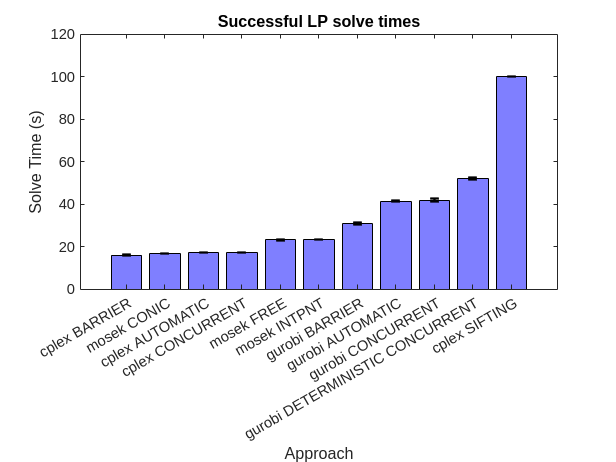

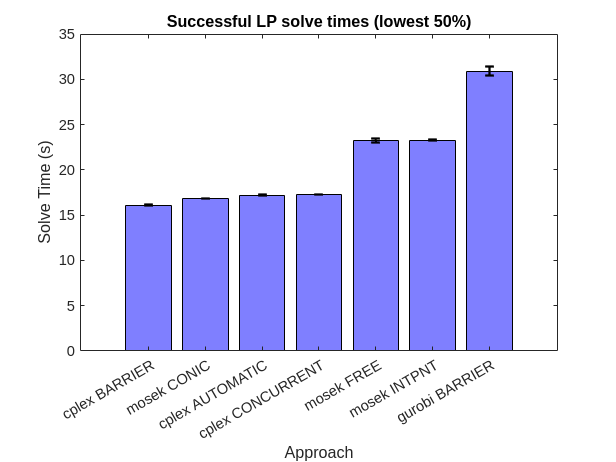

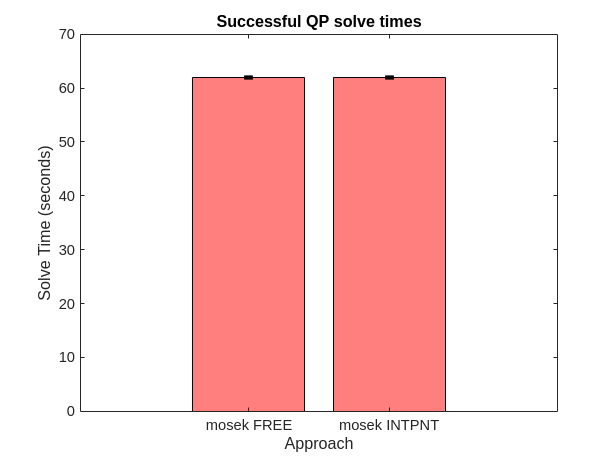

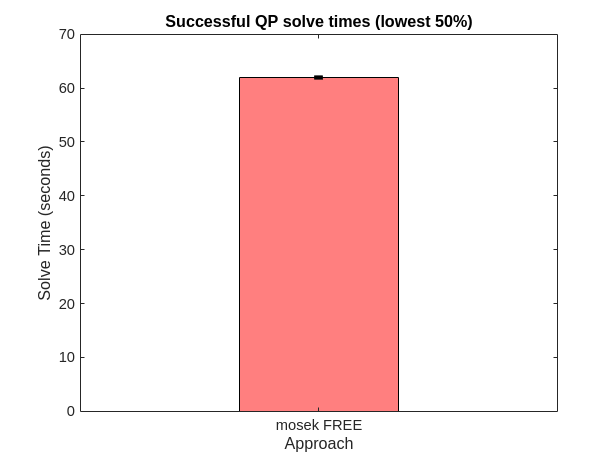

if 1
    if 0
        % Create the first histogram
        histogram(T.time(T.stat==1 & strcmp(T.problem,'LP')),'NumBins',100,'FaceColor', 'r','FaceAlpha', 0.5);  % 'r' sets the color to red
        hold on;  % Keep the current plot so that the second histogram is overlaid

        % Create the second histogram
        histogram(T.time(T.stat==1 & strcmp(T.problem,'QP')),'NumBins',100,'FaceColor', 'b','FaceAlpha', 0.5);  % 'r' sets the color to red
        xlabel({'Whole body metabolic model LP solution time (seconds)',[int2str(nMet) ' metabolites, ' int2str(nRxn) ' reactions.']})
        ylabel('Number of solutions')
        title('Solution time depends on solver, method and problem');
        legend('LP', 'QP');
        hold off;  % Release the hold for future plots

    else

        if ~exist('T0','var')
            T0 = T;
        else
            T = T0;
        end

        % Concatenate solver and method into 'approach'
        T.approach = append(T.solver, ' ', T.method);
        T = T(strcmp(T.problem,'LP') & T.stat==1,:);
        % Calculate the mean solve time and standard deviation for each approach
        avg_times = varfun(@mean, T, 'InputVariables', 'time', 'GroupingVariables', 'approach');
        std_times = varfun(@std, T, 'InputVariables', 'time', 'GroupingVariables', 'approach');

        times = avg_times;
        times.std_time = std_times.std_time;
        % Sort both the avg_times and std_times by the mean solve time
        [times, sort_idx] = sortrows(times, 'mean_time');

        figure
        % Create a bar plot with the sorted data
        b = bar(times.mean_time, 'FaceColor', 'b', 'FaceAlpha', 0.5);
        hold on;

        % Add error bars using the sorted standard deviations
        errorbar(times.mean_time, times.std_time, 'k', 'linestyle', 'none', 'LineWidth', 1.5);
        xticks(1:length(times.approach))
        xticklabels(times.approach)

        % Add labels and title
        xlabel('Approach', 'Interpreter', 'none');
        ylabel('Solve Time (s)');
        title('Successful LP solve times', 'Interpreter', 'none');

        if size(T,1)>1
            figure
            % fastest times
            times = times(times.mean_time<mean(times.mean_time),:);
            % Create a bar plot with the sorted data
            b = bar(times.mean_time, 'FaceColor', 'b', 'FaceAlpha', 0.5);
            hold on;

            % Add error bars using the sorted standard deviations
            errorbar(times.mean_time, times.std_time, 'k', 'linestyle', 'none', 'LineWidth', 1.5);
            xticks(1:length(times.approach))
            xticklabels(times.approach)

            % Add labels and title
            xlabel('Approach', 'Interpreter', 'none');
            ylabel('Solve Time (s)');
            title('Successful LP solve times (lowest 50%)', 'Interpreter', 'none');
        end


        T = T0;
        % Concatenate solver and method into 'approach'
        T.approach = append(T.solver, ' ', T.method);
        figure
        T = T(strcmp(T.problem,'QP') & T.stat==1,:);
        % Calculate the mean solve time and standard deviation for each approach
        avg_times = varfun(@mean, T, 'InputVariables', 'time', 'GroupingVariables', 'approach');
        std_times = varfun(@std, T, 'InputVariables', 'time', 'GroupingVariables', 'approach');
        times = avg_times;
        times.std_time = std_times.std_time;
        % Sort both the avg_times and std_times by the mean solve time
        [times, sort_idx] = sortrows(times, 'mean_time');

        % Create a bar plot with the sorted data
        b = bar(times.mean_time, 'FaceColor', 'r', 'FaceAlpha', 0.5);
        hold on;

        % Add error bars using the sorted standard deviations
        errorbar(times.mean_time, times.std_time, 'k', 'linestyle', 'none', 'LineWidth', 1.5);
        xticks(1:length(times.approach))
        xticklabels(times.approach)

        % Add labels and title
        xlabel('Approach', 'Interpreter', 'none');
        ylabel('Solve Time (seconds)');
        title('Successful QP solve times', 'Interpreter', 'none');

        if size(T,1)>1
            figure
            % fastest times
            times = times(times.mean_time<mean(times.mean_time),:);
            % Create a bar plot with the sorted data
            b = bar(times.mean_time, 'FaceColor', 'r', 'FaceAlpha', 0.5);
            hold on;
            % Add error bars using the sorted standard deviations
            errorbar(times.mean_time, times.std_time, 'k', 'linestyle', 'none', 'LineWidth', 1.5);
            xticks(1:length(times.approach))
            xticklabels(times.approach)

            % Add labels and title
            xlabel('Approach', 'Interpreter', 'none');
            ylabel('Solve Time (seconds)');
            title('Successful QP solve times (lowest 50%)', 'Interpreter', 'none');
        end
    end
end